syms a b c t h
time=[0:9]

time =      0     1     2     3     4     5     6     7     8     9


height=[450 445 431 408 375 332 279 216 143 61]

height =    450   445   431   408   375   332   279   216   143    61


scatter(time,height)
hold on
h(t)=a*t*t+b*t+c

$$h(t) = a\,t^{2}+b\,t+c$$

eq=[h(0)==450 h(4)==375 h(9)==61]

$$eq = \left(\begin{array}{ccc} c=450 & 16\,a+4\,b+c=375 & 81\,a+9\,b+c=61 \end{array}\right)$$

[a b c]=solve(eq,[a b c])

$$a = -\frac{881}{180}$$

$$b = \frac{149}{180}$$

$$c = 450$$

h(t)=subs(h(t))

$$h(t) = -\frac{881\,t^{2}}{180}+\frac{149\,t}{180}+450$$

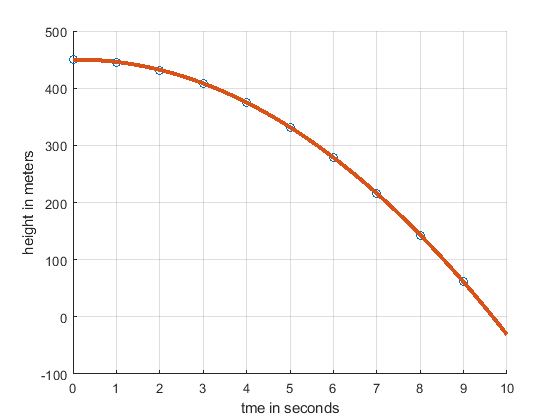

fplot(h(t),[0,10],'LineWidth',3)
grid on
xlabel("tme in seconds")
ylabel("height in meters")

t_pred=double(solve(h(t)==0,t>0))

t_pred = 9.6735